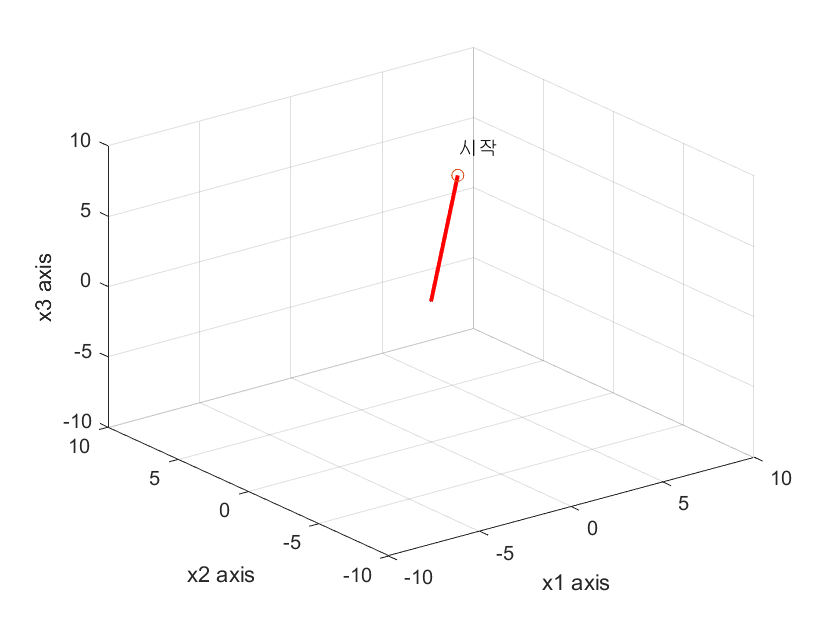

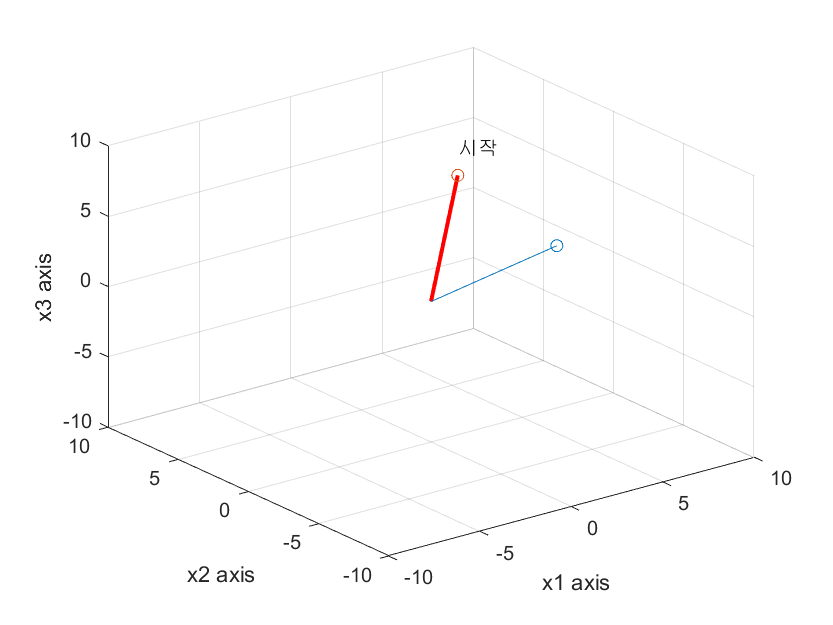

%강의노트 p30 의 ex3 번을 연속적으로 1도씩 회전하는 애니메이션이 되도록하는 Matlab 코드를 작성하고
% 애니메이션을 영상으로 캡쳐하여 ppt 에 첨부할 것. 

% x1축기준으로 1 도씩 60 도 회전한 후,
% x2축을 기준으로 1 도씩 45 도 회전하고
% x3축을 기준으로 1도씩 30 도로 연속으로 회전하는 애니메이션이 되야함. 

% 애니메이션에서의 viewpoint 는 각자 자신이 원하는 값으로 하나로 고정할 것.

clear; clf;
hold on;grid on;
xlabel('x1 axis'); ylabel('x2 axis'); zlabel('x3 axis');
axis([-10 10 -10 10 -10 10]);

x=[3;2;7];
view(45,45)

a2r=pi/180; % degree를 radian으로 바꾸기 위해

%x1축 CCW로 60도 회전
for i=0:1:60
    the=i*a2r;
    Rx=[1 0 0;0 cos(the) -sin(the);0 sin(the) cos(the)];% roll (x1축을 기준으로 회전)
    y1=Rx*x;
    clf; 
    plot3(y1(1),y1(2),y1(3),'o'); hold on;grid on;
    line([0 y1(1)],[0 y1(2)],[0 y1(3)]);
    view(45,45)
    xlabel('x1 axis'); ylabel('x2 axis'); zlabel('x3 axis');
    axis([-10 10 -10 10 -10 10]);

    line([0 x(1)],[0 x(2)],[0 x(3)],'color','red','Linewidth',2);
    plot3(x(1),x(2),x(3),'o'); 
    text(x(1),x(2),x(3)+2.5,'시작\newline점x');

    pause(0.01);
    
end

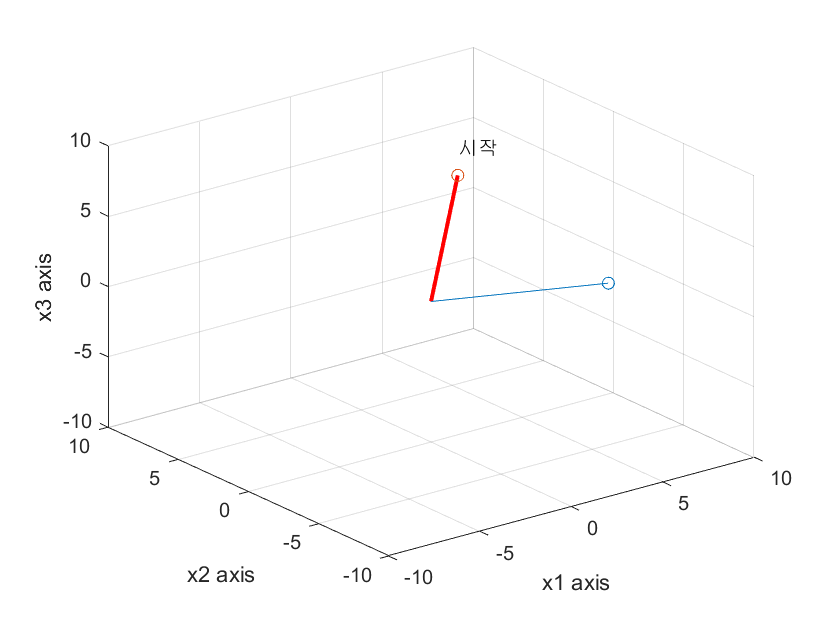


pause(0.5);
%x2축 CCW로 45도 회전
for i=0:1:45
    phi=i*a2r;
    Ry=[cos(phi) 0 sin(phi);0 1 0;-sin(phi) 0 cos(phi)];% pitch (x2축을 기준으로 회전)
    y2=Ry*y1; 
    clf; 
    plot3(y2(1),y2(2),y2(3),'o'); hold on;grid on;
    line([0 y2(1)],[0 y2(2)],[0 y2(3)]);
    view(45,45);
    xlabel('x1 axis'); ylabel('x2 axis'); zlabel('x3 axis');
    axis([-10 10 -10 10 -10 10]);

    line([0 x(1)],[0 x(2)],[0 x(3)],'color','red','Linewidth',2);
    plot3(x(1),x(2),x(3),'o'); 
    text(x(1),x(2),x(3)+2.5,'시작\newline점x');

    pause(0.01);
end


pause(0.5);
%x3축 CCW로 30도 회전
for i=0:1:30
    psi=i*a2r;
    Rz=[cos(psi) -sin(psi) 0;sin(psi) cos(psi) 0;0 0 1]; % yaw (x3축을 기준으로 회전)
    y3=Rz*y2;
    clf; 
    plot3(y3(1),y3(2),y3(3),'o'); hold on; grid on;
    line([0 y3(1)],[0 y3(2)],[0 y3(3)]);
    view(45,45)
    xlabel('x1 axis'); ylabel('x2 axis'); zlabel('x3 axis');
    axis([-10 10 -10 10 -10 10]);

    line([0 x(1)],[0 x(2)],[0 x(3)],'color','red','Linewidth',2);
    plot3(x(1),x(2),x(3),'o'); 
    text(x(1),x(2),x(3)+2.5,'시작\newline점x');

    pause(0.01);
end

y=Rz*Ry*Rx*x

y =     7.5722
   -1.4735
    1.5783


y3

y3 =     7.5722
   -1.4735
    1.5783


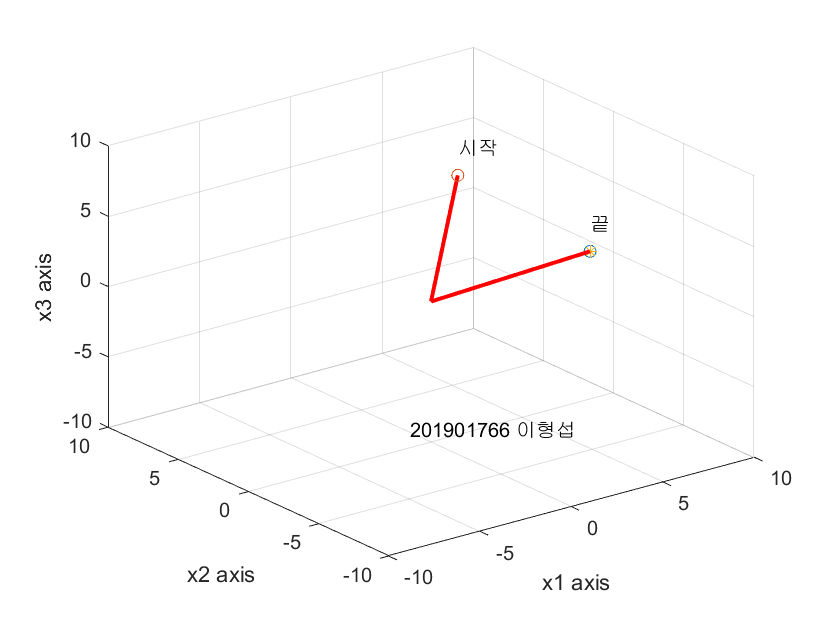


line([0 y(1)],[0 y(2)],[0 y(3)],'color','red','Linewidth',2);
plot3(y(1),y(2),y(3),'*');text(y(1),y(2),y(3)+2.5,'끝\newline점y');
text(-5,-5,-5,'201901766 이형섭');